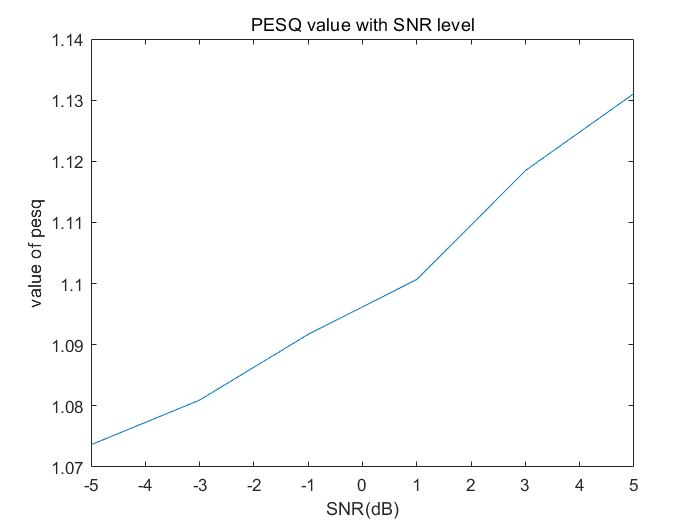

[s,fs]=audioread('mhint_01_01.wav');
y_1=awgn(s,-5,'measured');
y_2=awgn(s,-3,'measured');
y_3=awgn(s,-1,'measured');
y_4=awgn(s,1,'measured');
y_5=awgn(s,3,'measured');
y_6=awgn(s,5,'measured');

equalize_y_1=y_1/norm(y_1)*norm(s);
equalize_y_2=y_2/norm(y_2)*norm(s);
equalize_y_3=y_3/norm(y_3)*norm(s);
equalize_y_4=y_4/norm(y_4)*norm(s);
equalize_y_5=y_5/norm(y_5)*norm(s);
equalize_y_6=y_6/norm(y_6)*norm(s);

audiowrite('equalize_y_1.wav',equalize_y_1,fs);
audiowrite('equalize_y_2.wav',equalize_y_2,fs);
audiowrite('equalize_y_3.wav',equalize_y_3,fs);
audiowrite('equalize_y_4.wav',equalize_y_4,fs);
audiowrite('equalize_y_5.wav',equalize_y_5,fs);
audiowrite('equalize_y_6.wav',equalize_y_6,fs);

score1=pesq('mhint_01_01.wav','equalize_y_1.wav');
score2=pesq('mhint_01_01.wav','equalize_y_2.wav');
score3=pesq('mhint_01_01.wav','equalize_y_3.wav');
score4=pesq('mhint_01_01.wav','equalize_y_4.wav');
score5=pesq('mhint_01_01.wav','equalize_y_5.wav');
score6=pesq('mhint_01_01.wav','equalize_y_6.wav');

plot([-5,-3,-1,1,3,5],[score1,score2,score3,score4,score5,score6]);
xlabel('SNR(dB)');
ylabel('value of pesq');
title('PESQ value with SNR level')